# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.3 知乎提问

#### 1.3.3 计算心形线的面积

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

# 如何用matlab计算不光滑曲面（函数）的二重积分？

原问题：[https://www.zhihu.com/question/647456852/answer/3423774746](https://www.zhihu.com/question/647456852/answer/3423774746)

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


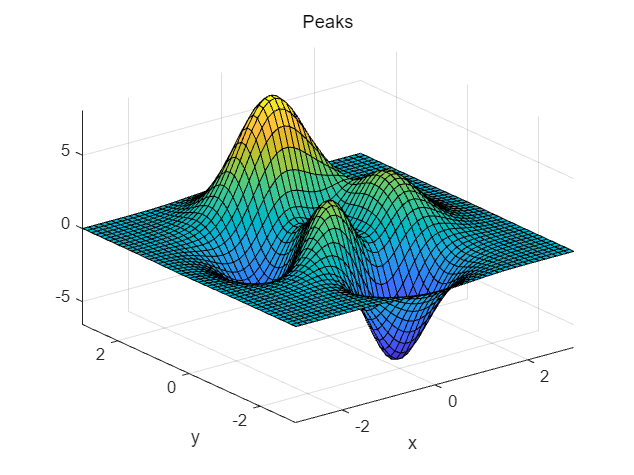

clear;clc;
peaks

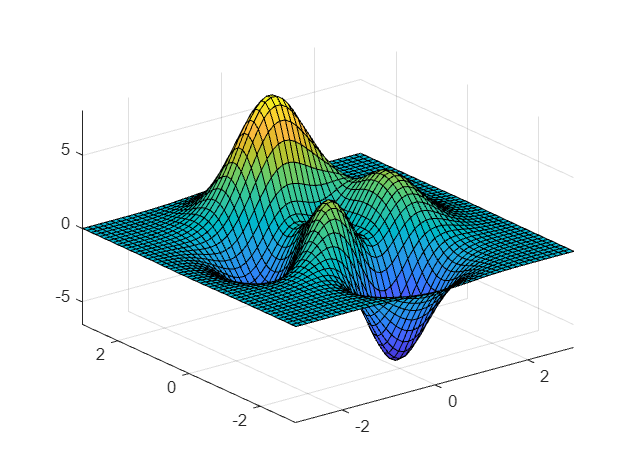

[x, y, z] = peaks(50);
surf(x, y, z);
axis tight

 
z =  3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2) 
 


% 类似积分上下限
% 从 -3 到 3 等分 50 份
xs = x(1, :);
ys = y(:, 1);
% 如果知道被积分函数的表达式，可以使用以下函数做数值积分
peaks

func = @(x, y) 3*(1-x).^2.*exp(-(x.^2) - (y+1).^2) ... 
   - 10*(x/5 - x.^3 - y.^5).*exp(-x.^2-y.^2) ... 
   - 1/3*exp(-(x+1).^2 - y.^2);
 
result = integral2(func, -3, 3, -3, 3)

result = 13.0571

% 只有数据怎么办
dx = xs(2) - xs(1);
dy = ys(2) - ys(1);
sumi = 0;
for i = 1:50-1
    for j = 1:50-1
        % 取临近四个点的均值
        f = (z(i, j) + z(i, j + 1) + z(i + 1, j) + z(i + 1, j + 1)) / 4;
        sumi = sumi + f * dx * dy;
    end
end
sumi

sumi = 13.0563

[xq, yq] = meshgrid(linspace(-3, 3, 100));
zq = griddata(x, y, z, xq, yq, 'cubic');
xs = xq(1, :);
ys = yq(:, 1);
dx = xs(2) - xs(1);
dy = ys(2) - ys(1);
sumi = 0;
for i = 1:100-1
    for j = 1:100-1
        % 取临近四个点的均值
        f = (zq(i, j) + zq(i, j + 1) + zq(i + 1, j) + zq(i + 1, j + 1)) / 4;
        sumi = sumi + f * dx * dy;
    end
end
sumi

sumi = 13.0572